## This exercise explores periodic signals, fourier transforms and spectral power

`Copyright © 2020 Danica Roth <droth@mines.edu>`

`GNU General Public License`

First, clear working memory and figures (good practice for any Matlab script):

clear
close all

## Periodic Signals and Spectra: Functional Definitions

### Sinusoids in the spatial domain

A **sine wave** or **sinusoid** is a continuous mathematical function describing a periodic oscillation:

             $y\left(x\right)=A\;\sin \left(2\pi \;f\;x\;+\;\phi \right)+D=A\;\sin \left(\omega \;x\;+\;\phi \right)+D$,

where   $A=\textrm{amplitude}$

            
$$f=\textrm{frequency}\;\left(\textrm{cycles}\;\textrm{per}\;\textrm{unit}\;x\right)$$


            
$$\omega =2\pi f=\textrm{angular}\;\textrm{frequency}\;\left(\textrm{radians}\;\textrm{per}\;\textrm{unit}\;x\right)$$


            
$$\phi =\textrm{phase}\;\textrm{offset}\;\left(\textrm{in}\;\textrm{radians}\right)$$


            
$$D=\textrm{mean}\;\textrm{offset},\;\textrm{in}\;\textrm{signal}\;\textrm{processing}\;\textrm{also}\;\textrm{called}\;\textrm{the}\;\textrm{DC}\;\textrm{component}$$


In this example, we will assume $D=0$ for simplicity.

Here, we are writing our sine wave as a function of $x$--which could be any variable, really. If we assume $x$ represents space, then this function lives in the **spatial domain**, i.e., it varies periodically in space. If we substitute $t$ or time for $x$, we would then have a function that is periodic in the **time domain**.

Next, we'll define an [anonymous function](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html) (syntactically denoted by the @ symbol) to easily create a sine wave $y\left(x\right)$ for any given $x$ array (which we will also define at this point) and set of input parameters $A$, $f$ and $\phi$ (which you will set below).

sine = @(x,A,f,phi,D) A.*sin(2.*pi.*f.*x + phi) + D; %anonymous function

We can plot this function as a symbolic expression using MATLAB's [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html) (which you must have enabled to run this section of the exercise--if you do not have it, the code below will just skip this section).

#### Play with the sliders below until you're sure you understand how each parameter controls the sinusoid.

$$y = \text{D}+A\,\sin\left(\varphi +2\,\pi \,f_{0}\,x\right)$$

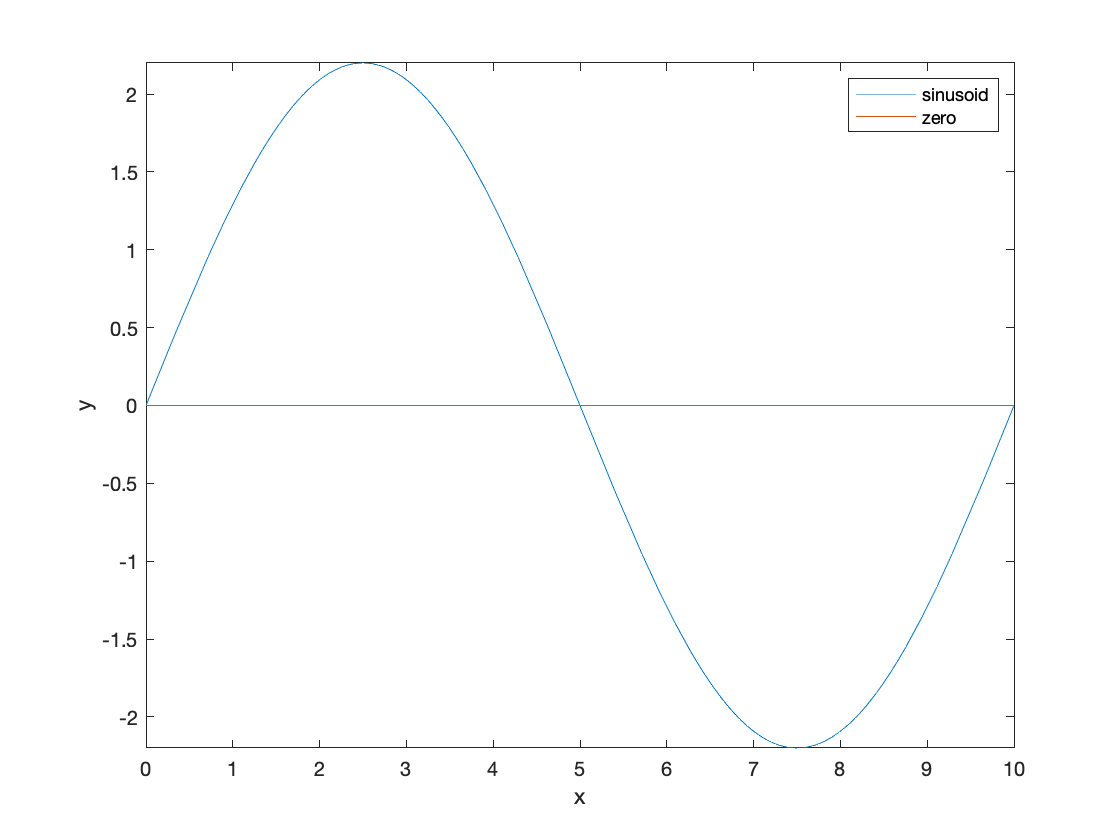

if contains(struct2array(ver), 'Symbolic Math Toolbox')
    syms x A f_0 phi D %create symbolic variables x, A, f, phi and D
    y = sine(x,A,f_0,phi,D) %call the anonymous function above to create a symbolic dependent variable y
    
    %Set parameters for the sine wave
    Aset = 2.2; %amplitude
    f_0set = 0.1; %frequency
    phiset = 0; %phase
    Dset = 2.5; %phase
    
    %Plot the sine wave
    figure(1);clf
    fplot(x,subs(y,[A f_0 phi D],[Aset f_0set phiset Dset]),[0 10])
    hold on
    plot([0 10],[0 0])
    xlabel('x')
    ylabel('y')
    legend('sinusoid','zero')
end

### Fourier transforms, spectral power and the frequency domain

The fourier transform of signal $y\left(x\right)$, here denoted $\hat{Y}$, is a function of frequency $f$ (i.e., $\hat{Y} \left(f\right)$ lives in the frequency domain) and can be defined as:

            
$$\hat{Y} \left(f\right)=$$

$${\displaystyle {\mathcal {F}}\{y(x)\}}$$

$$=\int_{-\infty }^{\infty } y\left(x\right)e^{-2\pi ifx} \;dx$$


The fourier transform of our sinusoid is a delta function, which will be easier to visualize with a simpler version of our sinusoid, so we will assume $D=\phi =0$ for the following exercise.

*(Also note that there are multiple valid conventions around the definition of a fourier transform, which is why MATLAB's Symbolic Math Toolbox allows customizaton of fourier transforms through the 'FourierParameters' field--the lines below set it to use the definition referenced above)*

if contains(struct2array(ver), 'Symbolic Math Toolbox')
    syms f %create symbolic frequency variable
    y = sine(x,A,f_0,0,0) %create symbolic function with D=phi=0
    sympref('FourierParameters',[1 -2*sym(pi)]); %set definition to follow above convention
    Y = fourier(y,x,f) %compute symbolic fourier transform 
end

$$y = A\,\sin\left(2\,\pi \,f_{0}\,x\right)$$

$$Y = -\pi \,A\,\left(\delta (2\,\pi \,f-2\,\pi \,f_{0})-\delta (2\,\pi \,f+2\,\pi \,f_{0})\right)\,\mathrm{i}$$

The fourier transform of $y\left(x\right)$ is:


$$\hat{Y} \left(f\right)=-\pi \;A\left(\delta \left(2\pi f-2\pi f_0 \right)-\delta \left(2\pi f+2\pi f_0 \right)\right)i$$


where $\delta \;\left(a\right)$ is the the dirac delta function, which is heuristically defined as $\delta \left(a\right)=0$ for all $a\not= 0$, and $\infty$ for $a=0$, and satisfies the identity,

            
$$\int_{-\infty }^{\infty } \delta \;\left(a\right)\;\textrm{da}=1$$


Hence, a dirac delta function with $\delta \left(2\pi f\pm {2\pi f}_0 \right)$ is infinite at frequencies $\mp f_0$ and zero at all other frequencies. Assuming amplitude A is positive, this means that 

           
$$\hat{Y} \left(f=f_0 \right)=-i\infty \;$$


and     $\hat{Y} \left(f\not= f_0 \right)=0$

We can confirm this by evaluating $\hat{Y} \left(f\right)$ at $f=f_0$:

assume(A,'positive')
Y_f0 = subs(Y,f,f_0)

$$Y\_f0 = -\mathrm{i}\,\infty$$

The power $P_{\mathrm{yy}} \left(f\right)$ of a continuous function $y\left(x\right)$ is the fourier transform of its auto-correlation function:


$$P_{\mathrm{yy}} \left(f\right)={\left|\hat{Y} \left(f\right)\right|}^2 =$$

$${\displaystyle {\mathcal {F}}\{y(x)\ast y(-x)\}$$


P=abs(Y).^2

$$P = A^{2}\,\pi^{2}\,{\left|\delta (2\,\pi \,f-2\,\pi \,f_{0})-\delta (2\,\pi \,f+2\,\pi \,f_{0})\right|}^{2}$$

P_f0 = subs(P,f,f_0)

$$P\_f0 = \infty$$

Parseval's theorem states that total signal energy $E$ is conserved:

           
$$E=\int_{-\infty }^{\infty } {\left|y\left(x\right)\right|}^2 dx=\int_{-\infty }^{\infty } {\left|\hat{Y} \left(f\right)\right|}^2 df$$
